# Exploration

The eegArtifacts.mlx script illustrates problems and solutions. This live script looks more generally at how simulation parameters affect performance.

## Setup Simulation

First define the stimulation and recording parameters.

startup; % Make sure all toolboxes are on the path

eegDefaults.reproducible              = true;    % Fix the random number generator to get reproducible results

Equipment:

eegDefaults.stimulatorSamplingRate    = 1e3;     % Neuroconn (2 kHz)
eegDefaults.recordingSamplingRate     = 5e3;     % 5kHz
eegDefaults.currentResolution         = 1e-6;    % 1 muA
eegDefaults.highPass                  = 0.01;    % Analog filter of the recording amplifier


Experiment:


eegDefaults.duration                  = 2*60;   % 2 min of data
eegDefaults.tacsFrequency             = 0;
eegDefaults.tacsAmplitude             = 0;
eegDefaults.tdcsMean                  = 0;

Signals. Setting everything except the background to 0.

eegDefaults.additive                  = 100e-6;   % Background Noise stdev
eegDefaults.lfpAmplitude              = 0;
eegDefaults.multiplicative            = 0;
eegDefaults.zAmplitude                = 0;


And setup the base parameters for artifiact removal

arDefaults.slide                     = false;   % No sliding segment
arDefaults.slack                     = 5e-3;    % 5 ms to realign segments
arDefaults.nrSegsPerWindow           = 10;      % 10 segments to average artifact
arDefaults.pcaNr                     = 2;       % First two PC are removed
arDefaults.pcaVarExplained           = Inf;     % Ignore explained variance, always remove 2.
arDefaults.pcaNrSegsPerWindow        = Inf;     % Use all segments (plus the tACS signal; below) to determine basis set.
arDefaults.referenceSegment          = 1;       % Align to first segment
arDefaults.recordingSamplingRate      = eegDefaults.recordingSamplingRate; % Match to the recording

## Signal frequency dependence

The above analysis focuses only on a single intrinsic oscillation, here I do repeat this for a range of frequencies to show that the relative performance of the methods is approximately the same no matter what the neural signal is. 

eeg                  = artSim(eegDefaults); % Start fresh
eeg.lfpAmplitude     = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth     = 1;        % Oscillation bandwidth.
eeg.tacsAmplitude    = 1e-3;    % 1 mA -> 1 mV artifact
eeg.tacsFrequency    = 8;      %  8 Hz

ar                 = arDefaults;
ar.tacsFrequency  = eeg.tacsFrequency;
ar.segmentDuration       = 30/eeg.tacsFrequency;      % 30 cycles per segment

methods = ["FASTR","FBAR", "RBAR"];
signalFreqs = 2.^(0:5);  % Test these frequencies
nrFreqs = numel(signalFreqs);
nrMethods = numel(methods);
forbiddenBand = nan(nrFreqs,nrMethods);
forbidden = nan(nrFreqs,nrMethods);
mre = nan(nrFreqs,nrMethods);
for m=1:nrMethods
    for  f = 1:nrFreqs
        eeg.lfpFrequency = signalFreqs(f);
        results = simPlotEEG(eeg,ar,methods(m),freqRes =0.1,axs=[nan nan nan]);  % Same analysis as above, without figure
        forbiddenBand(f,m) = results.forbiddenBand;
        forbidden(f,m) = results.forbidden;
        mre(f,m) = results.meanPctError;
    end
end

Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 19/100 muV ae = 3.1%)
Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 19/100 muV ae = 3.1%)
Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.98 rmse = 20/100 muV ae = 2.9%)
Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.94 rmse = 25/100 muV ae = 3.4%)
Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 19/100 muV ae = 3.1%)
Allocating memory...


ans = -0.0831


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 20/100 muV ae = 3.0%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 8/100 muV ae = 0.7%)
FBAR (r=0.96 rmse = 20/100 muV ae = 1.6%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=0.99 rmse = 8/100 muV ae = 0.6%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.5%)


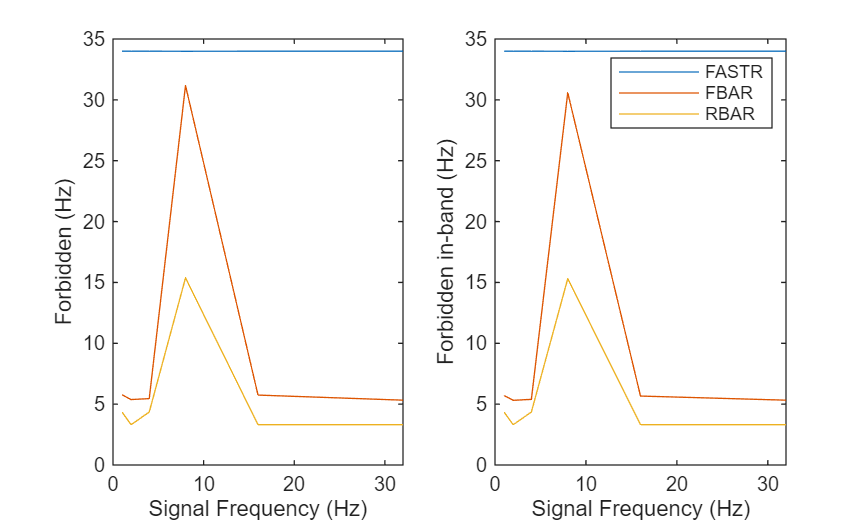

clf;
subplot(1,2,1)
plot(signalFreqs,forbidden)
xlabel 'Signal Frequency (Hz)'
ylabel 'Forbidden (Hz)'

subplot(1,2,2)
plot(signalFreqs,forbiddenBand)
xlabel 'Signal Frequency (Hz)'
ylabel 'Forbidden in-band (Hz)'
legend(cellstr(methods))

mean(forbidden)

ans =    33.9970    9.8083    5.6683


std(forbidden)

ans =     0.0031   10.4700    4.7820


mean(mre)

ans =     3.0993    0.8448    0.4766


The figure shows that FASTR  performs poorly across all signal frequencies while FBAR and RBAR create relatively small forbidden bands, as long as the signal frequency (i.e. the neural oscillation) is distinct from the tACS frequency.

## Segment length dependence

Longer segments generally result in better artifact estimation (as long as the artifact is not substantially the same as the neural signal) and therefore better artifact removal. 

Note, however, that this comes at a cost of a reduced ability to follow changes in the artifacts over time (i.e. dealing with non-stationary artifacts). The artifacts in these simulations are approximately stationary and therefore ignore this tradeoff. 

eeg = artSim(eegDefaults);
eeg.duration         = 600;
eeg.lfpFrequency     = 23;
eeg.lfpAmplitude     = 100e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth     = 5;        % Oscillation bandwidth.
eeg.additive         = 100e-6;   % Background
eeg.zAmplitude       = 0.05;     % 5% heartbeat artifact
eeg.zFun             = @zHeartbeat;
eeg.reproducible    = false;    % Random draws each sim
tacsFrequency =10;
ar = arDefaults;

segmentDuration     =   [1 5 10 20 40];
nrBootstrap         =10;  % Takes a while to run...

nrSegmentDurations = numel(segmentDuration);
methods = ["FASTR","FBAR", "RBAR"];
nrMethods = numel(methods);
stims = ["AC" "DC"];
nrStims = numel(stims);
forbidden = nan(nrSegmentDurations,nrMethods,nrStims,nrBootstrap);
mre = nan(nrSegmentDurations,nrMethods,nrStims,nrBootstrap);

for bs = 1:nrBootstrap
    for stim = 1:nrStims
        if stims(stim)=="AC"
            eeg.tacsAmplitude  = 1e-3;
            eeg.tacsFrequency  =tacsFrequency;
            eeg.tdcsMean  = 0;
        elseif stims(stim)== "DC"
            eeg.tacsAmplitude  = 0;
            eeg.tacsFrequency  =0;
            eeg.tdcsMean  = 1e-3;
        end
        for m=1:nrMethods
            for  s = 1:nrSegmentDurations
                ar.segmentDuration= segmentDuration(s);
                if stims(stim)=="AC"                    
                    ar.tacsFrequency = tacsFrequency;
                elseif stims(stim) =="DC"                    
                    ar.tacsFrequency = 0;
                end
                results = simPlotEEG(eeg,ar,methods(m),freqRes =0.1,axs=[nan nan nan]);
                forbidden(s,m,stim,bs) = results.forbiddenBand;
                mre(s,m,stim,bs) = results.meanPctError;
            end
        end
    end
end

Allocating memory...


ans = 0.1337


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 33/100 muV ae = 3.6%)
Allocating memory...


ans = 0.1278


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 2.3%)
Allocating memory...


ans = -0.0095


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 6 sec.
FASTR (r=0.97 rmse = 30/100 muV ae = 2.1%)
Allocating memory...


ans = -0.0157


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 21 sec.
FASTR (r=0.98 rmse = 30/100 muV ae = 1.8%)


Allocating memory...


ans = -0.0621


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 21 sec.
FASTR (r=0.96 rmse = 38/100 muV ae = 3.0%)
FBAR (r=1.00 rmse = 9/100 muV ae = 1.4%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.8%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
Allocating memory...


ans = -0.0963


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.94 rmse = 35/100 muV ae = 4.5%)
Allocating memory...


ans = 0.1396


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 25/100 muV ae = 2.3%)
Allocating memory...


ans = 0.0400


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 9 sec.
FASTR (r=0.97 rmse = 25/100 muV ae = 2.4%)
Allocating memory...


ans = 0.0354


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 32 sec.
FASTR (r=0.98 rmse = 25/100 muV ae = 2.1%)


Allocating memory...


ans = -0.2022


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 30 sec.
FASTR (r=0.96 rmse = 31/100 muV ae = 3.3%)
FBAR (r=0.97 rmse = 33/100 muV ae = 1.2%)
FBAR (r=0.94 rmse = 43/100 muV ae = 0.9%)
FBAR (r=0.99 rmse = 24/100 muV ae = 0.7%)
FBAR (r=0.97 rmse = 32/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 20/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.1%)
Allocating memory...


ans = -0.0663


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.96 rmse = 36/100 muV ae = 3.4%)
Allocating memory...


ans = -0.0389


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 2.3%)
Allocating memory...


ans = 0.1176


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 5 sec.
FASTR (r=0.98 rmse = 29/100 muV ae = 2.0%)
Allocating memory...


ans = -0.2955


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 27 sec.
FASTR (r=0.98 rmse = 30/100 muV ae = 1.9%)


Allocating memory...


ans = -0.2404


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 29 sec.
FASTR (r=0.96 rmse = 38/100 muV ae = 3.0%)
FBAR (r=1.00 rmse = 9/100 muV ae = 1.4%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.8%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
Allocating memory...


ans = -0.0657


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 1 sec.
FASTR (r=0.88 rmse = 49/100 muV ae = 4.5%)
Allocating memory...


ans = -0.1757


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 24/100 muV ae = 2.5%)
Allocating memory...


ans = -0.0567


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 5 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.4%)
Allocating memory...


ans = -0.1809


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 21 sec.
FASTR (r=0.98 rmse = 24/100 muV ae = 2.3%)


Allocating memory...


ans = -0.0583


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 20 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 3.1%)
FBAR (r=0.79 rmse = 87/100 muV ae = 1.2%)
FBAR (r=0.95 rmse = 39/100 muV ae = 0.8%)
FBAR (r=0.98 rmse = 21/100 muV ae = 0.7%)
FBAR (r=0.95 rmse = 37/100 muV ae = 0.7%)
FBAR (r=0.97 rmse = 24/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
Allocating memory...


ans = -0.1509


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 1 sec.
FASTR (r=0.95 rmse = 39/100 muV ae = 3.6%)
Allocating memory...


ans = -0.0520


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 30/100 muV ae = 2.4%)
Allocating memory...


ans = -0.0672


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 5 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 2.3%)
Allocating memory...


ans = -0.0140


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 24 sec.
FASTR (r=0.97 rmse = 30/100 muV ae = 1.9%)


Allocating memory...


ans = -0.1173


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 20 sec.
FASTR (r=0.96 rmse = 38/100 muV ae = 2.9%)
FBAR (r=1.00 rmse = 9/100 muV ae = 1.4%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.9%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
Allocating memory...


ans = 0.1509


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 1 sec.
FASTR (r=0.94 rmse = 30/100 muV ae = 5.2%)
Allocating memory...


ans = 0.0156


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 24/100 muV ae = 2.5%)
Allocating memory...


ans = -0.0654


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 5 sec.
FASTR (r=0.97 rmse = 25/100 muV ae = 2.4%)
Allocating memory...


ans = 0.1071


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 20 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.2%)


Allocating memory...


ans = 0.1128


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 19 sec.
FASTR (r=0.96 rmse = 31/100 muV ae = 3.5%)
FBAR (r=0.98 rmse = 27/100 muV ae = 1.2%)
FBAR (r=0.94 rmse = 41/100 muV ae = 0.7%)
FBAR (r=0.97 rmse = 35/100 muV ae = 0.8%)
FBAR (r=0.99 rmse = 13/100 muV ae = 0.6%)
FBAR (r=0.97 rmse = 29/100 muV ae = 0.9%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.1%)
Allocating memory...


ans = -0.0445


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 1 sec.
FASTR (r=0.95 rmse = 42/100 muV ae = 3.6%)
Allocating memory...


ans = 0.0473


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 2.2%)
Allocating memory...


ans = 0.0500


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.98 rmse = 29/100 muV ae = 2.2%)
Allocating memory...


ans = 0.0585


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 31 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 1.9%)


Allocating memory...


ans = 0.1172


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 25 sec.
FASTR (r=0.96 rmse = 36/100 muV ae = 3.0%)
FBAR (r=1.00 rmse = 9/100 muV ae = 1.6%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.9%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
Allocating memory...


ans = -0.0527


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.94 rmse = 32/100 muV ae = 5.1%)
Allocating memory...


ans = -0.0670


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.5%)
Allocating memory...


ans = -0.0186


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.2%)
Allocating memory...


ans = 0.1338


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 30 sec.
FASTR (r=0.98 rmse = 24/100 muV ae = 2.3%)


Allocating memory...


ans = 0.0495


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 28 sec.
FASTR (r=0.96 rmse = 31/100 muV ae = 3.4%)
FBAR (r=0.91 rmse = 52/100 muV ae = 1.1%)
FBAR (r=0.98 rmse = 26/100 muV ae = 0.7%)
FBAR (r=0.97 rmse = 32/100 muV ae = 0.8%)
FBAR (r=0.98 rmse = 30/100 muV ae = 0.8%)
FBAR (r=0.98 rmse = 31/100 muV ae = 0.9%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
Allocating memory...


ans = -0.0092


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.95 rmse = 44/100 muV ae = 3.6%)
Allocating memory...


ans = 0.1055


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.98 rmse = 29/100 muV ae = 2.2%)
Allocating memory...


ans = 0.0472


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 2.1%)
Allocating memory...


ans = 0.0856


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 32 sec.
FASTR (r=0.98 rmse = 28/100 muV ae = 1.9%)


Allocating memory...


ans = -0.0363


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 27 sec.
FASTR (r=0.96 rmse = 39/100 muV ae = 3.1%)
FBAR (r=1.00 rmse = 10/100 muV ae = 1.5%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.8%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
Allocating memory...


ans = 0.1485


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.95 rmse = 26/100 muV ae = 5.4%)
Allocating memory...


ans = -0.0126


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 25/100 muV ae = 2.4%)
Allocating memory...


ans = -0.1317


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.3%)
Allocating memory...


ans = -0.0386


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 31 sec.
FASTR (r=0.98 rmse = 24/100 muV ae = 2.2%)


Allocating memory...


ans = -0.0208


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 28 sec.
FASTR (r=0.96 rmse = 31/100 muV ae = 3.3%)
FBAR (r=0.96 rmse = 37/100 muV ae = 1.3%)
FBAR (r=0.98 rmse = 23/100 muV ae = 0.8%)
FBAR (r=0.98 rmse = 25/100 muV ae = 0.7%)
FBAR (r=0.97 rmse = 23/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 9/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
Allocating memory...


ans = -0.0977


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 33/100 muV ae = 3.5%)
Allocating memory...


ans = 0.0234


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 2.3%)
Allocating memory...


ans = 0.0592


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 9 sec.
FASTR (r=0.98 rmse = 28/100 muV ae = 2.0%)
Allocating memory...


ans = 0.0080


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 33 sec.
FASTR (r=0.98 rmse = 29/100 muV ae = 2.0%)


Allocating memory...


ans = -0.0594


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 31 sec.
FASTR (r=0.96 rmse = 38/100 muV ae = 3.0%)
FBAR (r=1.00 rmse = 9/100 muV ae = 1.4%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.8%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.8%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
Allocating memory...


ans = 0.1312


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 1 sec.
FASTR (r=0.94 rmse = 33/100 muV ae = 4.4%)
Allocating memory...


ans = 0.0693


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 23/100 muV ae = 2.3%)
Allocating memory...


ans = 0.0039


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 5 sec.
FASTR (r=0.97 rmse = 25/100 muV ae = 2.2%)
Allocating memory...


ans = -0.0845


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 19 sec.
FASTR (r=0.98 rmse = 24/100 muV ae = 2.0%)


Allocating memory...


ans = -0.0770


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 18 sec.
FASTR (r=0.96 rmse = 31/100 muV ae = 3.4%)
FBAR (r=0.87 rmse = 69/100 muV ae = 1.3%)
FBAR (r=0.96 rmse = 34/100 muV ae = 0.8%)
FBAR (r=0.97 rmse = 34/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 20/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.6%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.9%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
Allocating memory...


ans = -0.1836


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.96 rmse = 34/100 muV ae = 3.6%)
Allocating memory...


ans = -0.1371


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.98 rmse = 30/100 muV ae = 2.3%)
Allocating memory...


ans = 0.0796


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.97 rmse = 28/100 muV ae = 2.1%)
Allocating memory...


ans = -0.1029


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 30 sec.
FASTR (r=0.98 rmse = 29/100 muV ae = 2.0%)


Allocating memory...


ans = -0.0845


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 28 sec.
FASTR (r=0.96 rmse = 37/100 muV ae = 2.9%)
FBAR (r=1.00 rmse = 9/100 muV ae = 1.5%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.8%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
Allocating memory...


ans = 0.1159


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.94 rmse = 32/100 muV ae = 4.9%)
Allocating memory...


ans = 0.0999


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 24/100 muV ae = 2.4%)
Allocating memory...


ans = -0.0081


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.3%)
Allocating memory...


ans = 0.0056


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 31 sec.
FASTR (r=0.98 rmse = 26/100 muV ae = 2.2%)


Allocating memory...


ans = -0.0104


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 29 sec.
FASTR (r=0.96 rmse = 31/100 muV ae = 3.4%)
FBAR (r=0.96 rmse = 39/100 muV ae = 1.2%)
FBAR (r=0.95 rmse = 38/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 17/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 12/100 muV ae = 0.7%)
FBAR (r=0.98 rmse = 16/100 muV ae = 0.6%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
Allocating memory...


ans = 0.1456


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.95 rmse = 42/100 muV ae = 3.7%)
Allocating memory...


ans = -0.0236


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.98 rmse = 30/100 muV ae = 2.3%)
Allocating memory...


ans = 0.0173


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.98 rmse = 30/100 muV ae = 2.3%)
Allocating memory...


ans = -0.0155


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 30 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 1.9%)


Allocating memory...


ans = -0.1056


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 30 sec.
FASTR (r=0.96 rmse = 36/100 muV ae = 3.0%)
FBAR (r=1.00 rmse = 10/100 muV ae = 1.5%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.8%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
Allocating memory...


ans = -0.0024


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.88 rmse = 59/100 muV ae = 4.2%)
Allocating memory...


ans = 0.0636


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 24/100 muV ae = 2.4%)
Allocating memory...


ans = 0.2765


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.3%)
Allocating memory...


ans = -0.0742


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 30 sec.
FASTR (r=0.98 rmse = 24/100 muV ae = 2.1%)


Allocating memory...


ans = 0.1213


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 29 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 3.2%)
FBAR (r=0.97 rmse = 30/100 muV ae = 1.1%)
FBAR (r=0.98 rmse = 24/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 21/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 22/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 11/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
Allocating memory...


ans = 0.0282


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 31/100 muV ae = 3.6%)
Allocating memory...


ans = -0.0807


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.98 rmse = 30/100 muV ae = 2.3%)
Allocating memory...


ans = -0.1151


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 9 sec.
FASTR (r=0.98 rmse = 30/100 muV ae = 1.8%)
Allocating memory...


ans = 0.0104


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 32 sec.
FASTR (r=0.98 rmse = 28/100 muV ae = 1.9%)


Allocating memory...


ans = 0.1705


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 29 sec.
FASTR (r=0.96 rmse = 39/100 muV ae = 3.1%)
FBAR (r=1.00 rmse = 10/100 muV ae = 1.4%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.9%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.6%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
Allocating memory...


ans = -0.0873


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.94 rmse = 31/100 muV ae = 5.1%)
Allocating memory...


ans = 0.0267


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 24/100 muV ae = 2.4%)
Allocating memory...


ans = 0.0396


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.97 rmse = 25/100 muV ae = 2.2%)
Allocating memory...


ans = -0.0369


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 32 sec.
FASTR (r=0.98 rmse = 26/100 muV ae = 2.1%)


Allocating memory...


ans = 0.0229


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 30 sec.
FASTR (r=0.97 rmse = 33/100 muV ae = 3.3%)
FBAR (r=0.96 rmse = 37/100 muV ae = 1.0%)
FBAR (r=0.96 rmse = 28/100 muV ae = 0.8%)
FBAR (r=0.98 rmse = 23/100 muV ae = 0.7%)
FBAR (r=0.99 rmse = 16/100 muV ae = 0.8%)
FBAR (r=0.98 rmse = 23/100 muV ae = 0.6%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.1%)
Allocating memory...


ans = -0.0274


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.95 rmse = 39/100 muV ae = 3.7%)
Allocating memory...


ans = -0.0436


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 3 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 2.3%)
Allocating memory...


ans = -0.1131


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 8 sec.
FASTR (r=0.98 rmse = 29/100 muV ae = 2.0%)
Allocating memory...


ans = -0.0715


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 31 sec.
FASTR (r=0.97 rmse = 29/100 muV ae = 1.9%)


Allocating memory...


ans = -0.0781


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 29 sec.
FASTR (r=0.96 rmse = 38/100 muV ae = 3.0%)
FBAR (r=1.00 rmse = 9/100 muV ae = 1.5%)
FBAR (r=1.00 rmse = 7/100 muV ae = 0.9%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.7%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
FBAR (r=1.00 rmse = 6/100 muV ae = 0.5%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.0%)
RBAR (r=1.00 rmse = 0/100 muV ae = 0.0%)
Allocating memory...


ans = -0.1031


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
..25% ..50% ..75% .100%
FASTR Finished in 0 min 1 sec.
FASTR (r=0.92 rmse = 40/100 muV ae = 4.7%)
Allocating memory...


ans = 0.0017


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
.25% 50% .75% 100%
FASTR Finished in 0 min 2 sec.
FASTR (r=0.97 rmse = 25/100 muV ae = 2.6%)
Allocating memory...


ans = -0.0140


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 5 sec.
FASTR (r=0.97 rmse = 26/100 muV ae = 2.2%)
Allocating memory...


ans = -0.1139


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 19 sec.
FASTR (r=0.98 rmse = 24/100 muV ae = 2.2%)


Allocating memory...


ans = -0.0463


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 18 sec.
FASTR (r=0.96 rmse = 32/100 muV ae = 3.4%)
FBAR (r=0.97 rmse = 33/100 muV ae = 1.1%)
FBAR (r=0.98 rmse = 24/100 muV ae = 0.8%)
FBAR (r=0.95 rmse = 45/100 muV ae = 0.8%)
FBAR (r=0.99 rmse = 12/100 muV ae = 0.6%)
FBAR (r=0.97 rmse = 22/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.8%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.3%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)


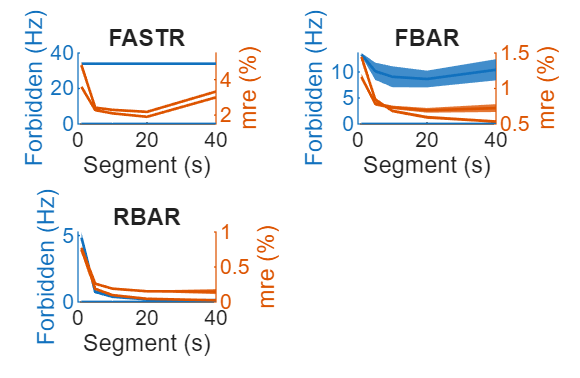


mForbidden = mean(forbidden,4);
mMre  = mean(mre,4);
sdForbidden = std(forbidden,0,4);
sdMre = std(mre,0,4);

[f,axs] = fig('Name','SegmentDuration','paperCols',1,'height',5,'nrRows',1,'nrCols',1);
tiledlayout('flow')
for m=1:nrMethods
    nexttile
    yyaxis left
    ploterr(segmentDuration',squeeze(mForbidden(:,m,:)),squeeze(sdForbidden(:,m,:)));
    xlabel 'Segment (s)'
    ylabel 'Forbidden (Hz)'
    yyaxis right
    ploterr(segmentDuration',squeeze(mMre(:,m,:)),squeeze(sdMre(:,m,:)))
    ylabel 'mre (%)'
    title (methods(m))    
end

The figure confirms that the mre decrease rapidly with increasing segment duration in RBAR  and FBAR. 

FASTR has some oddities with longer segment durations, but that is probably due to the way the averaging is done across segments. 